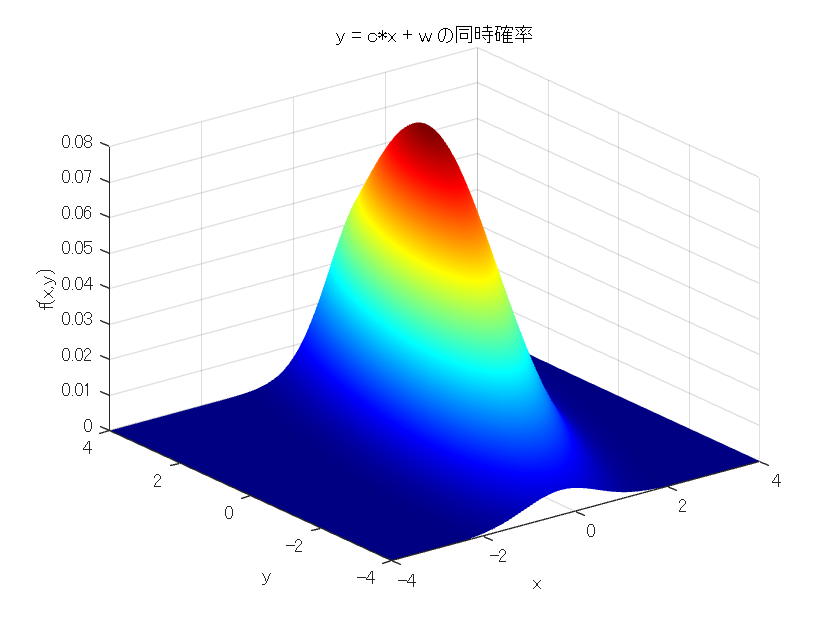

%--------------------------------------------
% y = c*x + w の場合の分布・サンプル・条件付期待値のプロット例
%--------------------------------------------
clear;

%% パラメータ設定
c = 1.5;           % 定数 c
mu_x = 1;        % xの平均
sigma_x = 1;     % xの標準偏差

mu_w = 0;        % wの平均
sigma_w = 2;     % wの標準偏差

% y = c*x + w のときのyの平均・分散、xとyの共分散の計算
mu_y = c * mu_x + mu_w;
sigma_y = sqrt(c^2 * sigma_x^2 + sigma_w^2);
cov_xy = c * sigma_x^2;

% (x,y)の2変量正規分布のパラメータ
mu = [mu_x, mu_y];
Sigma = [sigma_x^2,         cov_xy; 
         cov_xy,  c^2*sigma_x^2 + sigma_w^2];

%% プロット用の格子点の生成
x1 = -4:0.1:4;    % x軸の値
x2 = -4:0.1:4;    % y軸の値
[x, y] = meshgrid(x1, x2);

% 2変量正規分布の確率密度関数を計算
F = mvnpdf([x(:), y(:)], mu, Sigma);
F = reshape(F, length(x2), length(x1));

%% 1) 3次元サーフェスプロット
figure('Name','3D Surface');
surf(x1, x2, F);
xlabel('x');
ylabel('y');
zlabel('f(x,y)');
title('y = c*x + w の同時確率');
shading interp;    % 補間表示
colormap jet;

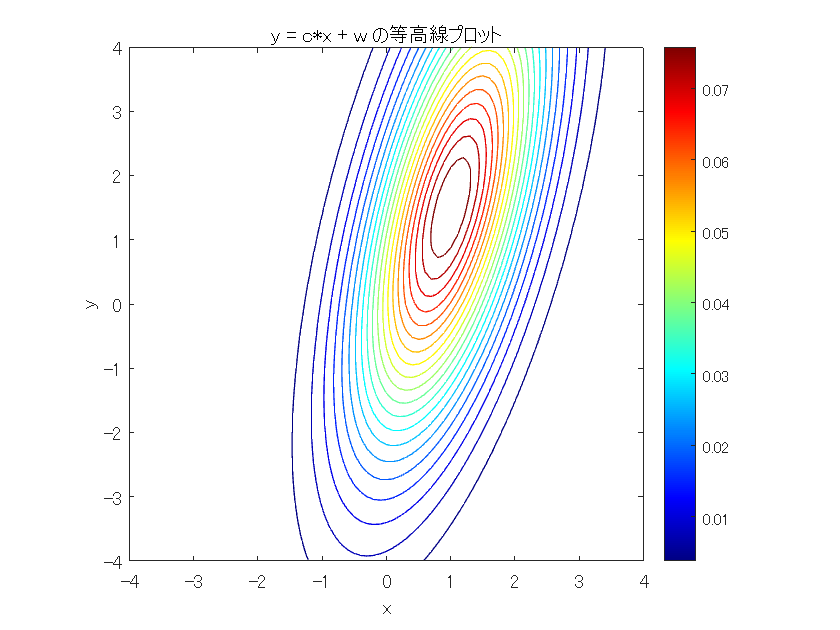


%% 2) 2次元等高線プロット
figure('Name','2D Contour');
contour(x1, x2, F, 20);  % 等高線20本
xlabel('x');
ylabel('y');
title('y = c*x + w の等高線プロット');
axis equal;        % 軸のスケールを等倍に
colormap jet;
colorbar;

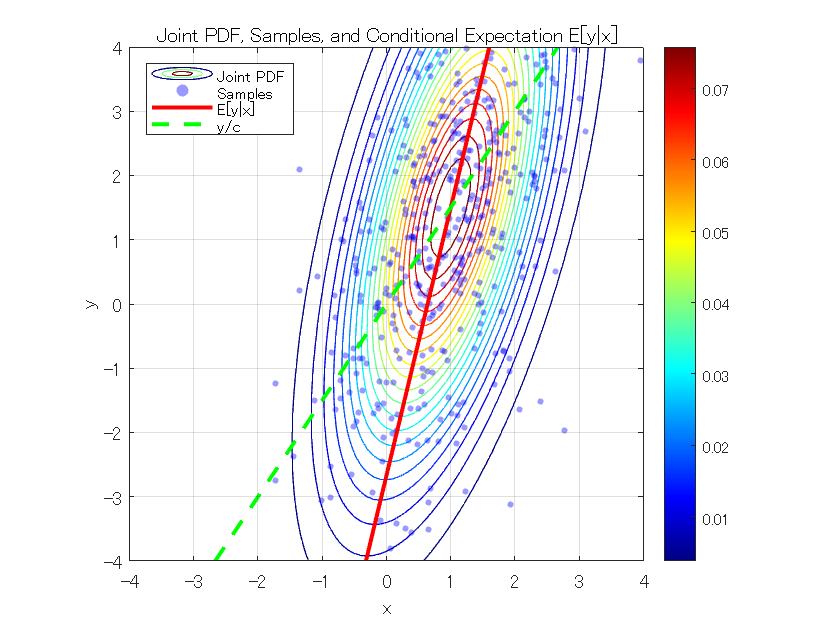


%% 条件付期待値のプロット
% サンプル生成
rng(1, "twister");   % 乱数シードの設定
num_samples = 500;
x_samples = normrnd(mu_x, sigma_x, num_samples, 1);
w_samples = normrnd(mu_w, sigma_w, num_samples, 1);
y_samples = c * x_samples + w_samples;
xy_samples = [x_samples, y_samples];

figure;
contour(x1, x2, F, 20);
axis equal;
colormap jet;
colorbar;
hold on;

% サンプルの散布図プロット
scatter(xy_samples(:,1), xy_samples(:,2), 10, 'b', 'filled', 'MarkerFaceAlpha', 0.4);

% 条件付期待値曲線 
y_line = linspace(-4, 4, 100);
mu_x_given_y = mu_x + sigma_x*c/(c*sigma_x*c+sigma_w^2)* (y(:, 1) - mu_y);
plot(mu_x_given_y, y(:, 1), 'r', 'LineWidth', 2);

simple_x = y(:, 1)/c;
plot(simple_x, y(:, 1), 'g--', 'LineWidth', 2);

xlabel('x');
ylabel('y');
title('Joint PDF, Samples, and Conditional Expectation E[y|x]');
grid on;
legend('Joint PDF', 'Samples', 'E[y|x]' , 'y/c', 'Location', 'northwest');
xlim([-4 4]);
ylim([-4 4]);